# CME192 Assignment 2, Part 2: Optimization

In this assignment, we use the Advertising dataset (ISLR) to study parameter estimation through optimization. Our goal is to predict Sales from TV, Radio, and Newspaper advertising spend using a linear model. Rather than treating regression as a closed-form formula, we frame it explicitly as an optimization problem: choose the parameter vector beta that minimizes mean squared error (MSE). In this way, we will practice solving both unconstrained and constrained problems using fminunc and fmincon. 

## Part A: Load the dataset + initial plotmatrix

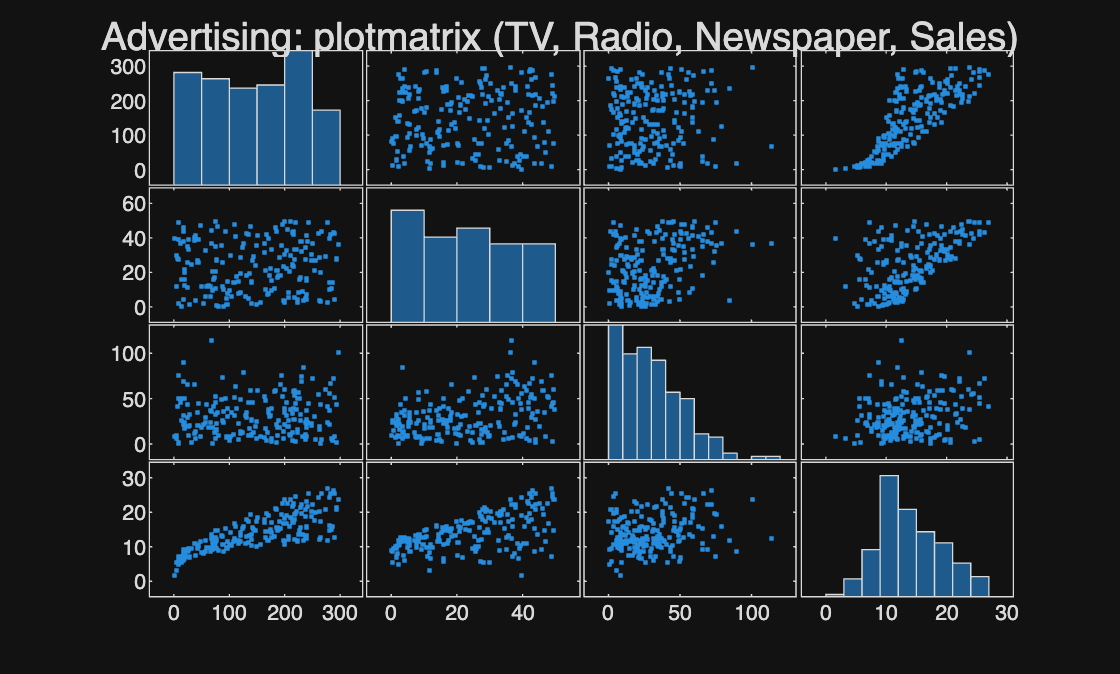

close all; clear; clc
rng(7)

url = "https://raw.githubusercontent.com/nguyen-toan/ISLR/master/dataset/Advertising.csv";
websave("Advertising.csv", url);
T = readtable("Advertising.csv");

if width(T) == 5
    T = T(:,2:end);
end

A = [T.TV, T.Radio, T.Newspaper, T.Sales];

figure("Name","Step 0: plotmatrix");
plotmatrix(A);
sgtitle("Advertising: plotmatrix (TV, Radio, Newspaper, Sales)");

## Part B: Correlation heatmap + normalize predictors

First, we use a correlation heatmap to get a big-picture view of which variables move together (and which predictors look most related to Sales). Then we normalize the predictors so TV, Radio, and Newspaper are on comparable scales. This helps iterative optimization methods like `fmincon` and `fminunc` take well-behaved steps instead of being dominated by whichever feature has the largest raw units. We normalize only the predictors, not the response `Sales`.

names = {'TV','Radio','Newspaper','Sales'};
C = corrcoef(A);

figure("Name","Step 1: Correlation heatmap");
h = heatmap(names, names, C);
h.CellLabelFormat = '%.2f';
h.ColorLimits = [-1 1];
title("Correlation heatmap (corrcoef)");

% TODO: Normalize
% Hint: Normalize Xraw (just the predictors) using standardizeCols
y = T.Sales;
Xraw = [T.TV, T.Radio, T.Newspaper];
[Z, muX, sigX] = _________________;
Xz = [ones(height(T),1), Z];

## Part C: Constrained optimization (fmincon) with slopes >= 0

In this step, we solve the regression problem under a simple domain-driven constraint: additional advertising spend should not reduce predicted sales. Mathematically, this means we enforce nonnegativity on the slope coefficients while leaving the intercept unconstrained. Because we standardized the predictors and each standard deviation is positive, requiring nonnegative slopes in standardized space is equivalent to requiring nonnegative slopes in the original units (scaling preserves sign). The objective is still the mean squared error, which is a convex quadratic function of the coefficients, and we are adding only simple bound constraints. Hence, `fmincon` can solve this efficiently. Feel free to try other constrained optimization techniques here instead! 

% Objective function handle (returns [f,g] like the lecture demo)
objMSE = @(beta) mseObjGrad(beta, Xz, y);

x0 = [0; 1e-2; 1e-2; 1e-2];
A = []; b = [];
lb = [-Inf; 0; 0; 0];
ub = inf(4,1);
options = optimset('GradConstr','on', 'GradObj','on', 'Display', 'iter');

% TODO: Optimize under the constraints
% Hint: Recall the lecture fmincon call signature and adapt.
% Lecture_06_Optimization.mlx -> "Demo"
[betaConZ, fvalCon, exitflagCon, outputCon] = ________________;

betaCon = unstandardizeBeta(betaConZ, muX, sigX);

disp("betaCon (constrained, ORIGINAL units):");
disp(betaCon);

## Part D: Unconstrained optimization (fminunc) with no constraints

We now solve the same least-squares objective, but without any bounds on the coefficients. This corresponds to the “standard” linear regression fit, obtained by minimizing mean squared error with no restrictions on the signs or magnitudes of the slopes. Here we use an iterative optimizer (`fminunc`) to compute that solution.

% TODO: Determine the options for the optimizer
% Hint: Turn on analytic gradients for the objective (GradObj = 'on') and
% show iterations (Display = 'iter').
optionsUnc = optimset('GradObj', ________, 'Display', ________);

% TODO: Optimize using fminunc
betaUncZ = ____________(objMSE, x0, _________);
betaUnc  = unstandardizeBeta(betaUncZ, muX, sigX);

disp("betaUnc (unconstrained, ORIGINAL units):");
disp(betaUnc);

## Results + plots

What to expect: 

- Constrained and unconstrained have roughly the same MSE and values in this analysis

- TV and Radio slopes are positive and fairly stable.

- Newspaper is often ~0 (and can be slightly negative) once TV/Radio are included.

X = [ones(height(T),1), Xraw];
yHatCon = X * betaCon;
yHatUnc = X * betaUnc;

mseCon = mean((yHatCon - y).^2);
mseUnc = mean((yHatUnc - y).^2);

fprintf("MSE (constrained)   = %.4f\n", mseCon);
fprintf("MSE (unconstrained) = %.4f\n", mseUnc);

coefTbl = table(betaCon, betaUnc, 'VariableNames', {'Constrained','Unconstrained'});
coefTbl.Properties.RowNames = {'Intercept','TV','Radio','Newspaper'};
disp(coefTbl);

figure("Name","Predicted vs Actual");
tl = tiledlayout(1,2,"TileSpacing","compact");
tl.Padding = "compact";

nexttile;
scatter(y, yHatCon, 28, "filled"); grid on;
xlabel("Actual Sales"); ylabel("Predicted Sales");
title(sprintf("Constrained (slopes >= 0), MSE=%.3f", mseCon), ...
    "FontWeight","bold", "Interpreter","none");
hold on; plot([min(y) max(y)], [min(y) max(y)], "k--", "LineWidth", 1.2); hold off;

nexttile;
scatter(y, yHatUnc, 28, "filled"); grid on;
xlabel("Actual Sales"); ylabel("Predicted Sales");
title(sprintf("Unconstrained, MSE=%.3f", mseUnc), ...
    "FontWeight","bold", "Interpreter","none");
hold on; plot([min(y) max(y)], [min(y) max(y)], "k--", "LineWidth", 1.2); hold off;

## Local functions (do not edit)

function [f, g] = mseObjGrad(beta, X, y)
% MSE objective and gradient for linear regression:
% f(beta) = (1/n)*||X*beta - y||^2
% g(beta) = (2/n)*X'*(X*beta - y)
n = size(X,1);
r = X*beta - y;
f = mean(r.^2);
g = (2/n) * (X' * r);
end

function [Z, mu, sigma] = standardizeCols(X, mu, sigma)
if nargin < 2 || isempty(mu)
    mu = mean(X, 1);
    sigma = std(X, 0, 1);
end
sigma(sigma == 0) = 1;
Z = (X - mu) ./ sigma;
end

function beta = unstandardizeBeta(betaZ, muX, sigX)
% Convert coefficients from standardized predictors back to original units.
% If y = b0 + sum b_j * (x_j - mu_j)/sig_j, then:
% beta_j = b_j / sig_j
% beta0  = b0 - sum( (b_j * mu_j)/sig_j )
b0 = betaZ(1);
b = betaZ(2:end);
beta = zeros(4,1);
beta(2:end) = b ./ sigX(:);
beta(1) = b0 - sum((b .* muX(:)) ./ sigX(:));
end